Estacionario base: Tca=43.66  Tsurf=39.45  Tins=37.00


heun         orden observado (último): 2.01
rk4          orden observado (último): 4.02
trapecio     orden observado (último): 2.00
euler_atras  orden observado (último): 0.99


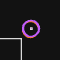

tau = [0.298 2.04 13.4] s | razón de rigidez = 44.8


h_crit Heun = 0.596 s | h_crit RK4 = 0.830 s


Descenso máximo = 0.787 °C | t_rec(90%) = 28.8 s | integral = 48.3 K*s


Ria=0.043  Tss=34.58  dmax=0.433  trec=21.4  I=26.3
Ria=0.116  Tss=38.67  dmax=1.081  trec=33.8  I=67.2
Rsi=0.011  Tss=37.67  dmax=0.778  trec=29.5  I=47.8
Rsi=0.032  Tss=36.36  dmax=0.785  trec=28.2  I=48.2
Rcs=0.018  Tss=38.29  dmax=0.766  trec=21.3  I=46.5
Rcs=0.055  Tss=35.95  dmax=0.772  trec=35.1  I=48.1
Csurf-50%  Tss=37.00  dmax=0.791  trec=22.8  I=48.2
Csurf+50%  Tss=37.00  dmax=0.778  trec=34.9  I=48.5
Cins-20%   Tss=37.00  dmax=0.789  trec=25.5  I=48.2
Cins+20%   Tss=37.00  dmax=0.784  trec=32.0  I=48.4
THex-2K    Tss=35.93  dmax=0.693  trec=28.8  I=42.6
THex+2K    Tss=38.07  dmax=0.880  trec=28.8  I=54.1


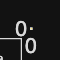

clear; clc; close all;

P = caso_base();
fprintf('C [J/K]  : Cca = %.2f | Csurf = %.1f | Cins = %.1f\n', P.C);
fprintf('T_Hex    : %.2f °C (T_ins,ss = 37 °C)\n', P.THex);
fprintf('m_out*cp : %.2f W/K durante la apertura (v = 0.10 m/s)\n', P.mcp_open);
T0 = estacionario(P, P.mcp_base);
fprintf('Estacionario base: Tca = %.2f | Tsurf = %.2f | Tins = %.2f °C\n\n', T0);

%% Tabla 3
ensayos = [15.1 0.89 1.45 0.85 3.04 0.010 0.018 0.011 0.043;
           20.1 1.63 2.66 1.57 5.58 0.020 0.034 0.020 0.072;
           25.0 2.58 4.19 2.47 8.79 0.030 0.055 0.032 0.116];
fprintf('TABLA 3 (publicado / modelo)\n');
for e = 1:size(ensayos,1)
    d = ensayos(e,:);
    pub = P.Tamb + [d(5)+d(4)+d(3), d(5)+d(4), d(5)];
    Q = P;  Q.R = struct('Rhex',d(6),'Rcs',d(7),'Rsi',d(8),'Ria',d(9));
    Q.THex = pub(1) + 0.5*d(2);
    mod = estacionario(Q, 0)';
    fprintf('E = %4.1f V | T_Hex = %.2f | Tca %.2f/%.2f | Tsurf %.2f/%.2f | Tins %.2f/%.2f\n', ...
            d(1), Q.THex, pub(1), mod(1), pub(2), mod(2), pub(3), mod(3));
end
fprintf('\n');

Rset = {rmin(), P.R, rmax()};  nombres = {'mínima','media','máxima'};
for k = 1:3
    Q = P;  Q.R = Rset{k};
    lam = sort(eig(sistema(Q,0)));
    fprintf('R %-7s: tau = %.2f, %.2f, %.2f s | razón de rigidez = %.1f\n', ...
            nombres{k}, -1./lam(3), -1./lam(2), -1./lam(1), lam(1)/lam(3));
end
fprintf('\n');

%% Figura 1
[t, T] = integrar('rk4', P, T0, 0.05, 250);
figure; plot(t, T - T0', 'LineWidth', 1.3); grid on
xlabel('Tiempo (s)'); ylabel('Desviación respecto al estado previo (°C)');
legend('T_{ca}','T_{surf}','T_{ins}','Location','southeast');
ic = round(P.t_close/0.05) + 1;
fprintf('Descenso al cierre: Tca = %.3f | Tsurf = %.3f | Tins = %.3f °C\n', T0 - T(ic,:)');
m = metricas(P);
Tabierto = estacionario(P, P.mcp_open);  asint = T0(3) - Tabierto(3);
fprintf('dTmax = %.3f °C (%.1f %% del asintótico %.3f) | t90 = %.1f s | I = %.1f K*s\n\n', ...
        m.dmax, 100*m.dmax/asint, asint, m.trec, m.I);

Tfrio = P.Tamb*ones(3,1);
h_lista = 0.5./2.^(0:7);
metodos = {'heun','rk4','trapecio','euler_atras'};
err = zeros(4, numel(h_lista));
for i = 1:4
    for k = 1:numel(h_lista)
        [t, T] = integrar(metodos{i}, P, Tfrio, h_lista(k), 300);
        err(i,k) = max(max(abs(T - solucion_exacta(P, Tfrio, t))));
    end
    fprintf('%-12s orden observado (últimos dos pasos) = %.2f | error con h = %.4f s: %.2e °C\n', ...
            metodos{i}, log2(err(i,end-1)/err(i,end)), h_lista(end), err(i,end));
end
fprintf('\n');
figure; loglog(h_lista, err', '-o'); grid on
xlabel('Paso de tiempo h (s)'); ylabel('Error máximo (°C)'); legend(metodos);

for k = 1:3
    Q = P;  Q.R = Rset{k};
    hc_heun = paso_critico('heun', Q);   hc_rk4 = paso_critico('rk4', Q);
    fprintf('R %-7s: h_c(Heun) = %.3f s | h_c(RK4) = %.3f s\n', nombres{k}, hc_heun, hc_rk4);
    if k == 2
        hc = [hc_heun hc_rk4];
    end
end
for i = 1:2                                 
    for fac = [0.9 1.1]
        if fac < 1, N = floor(60/(hc(i)*fac)); else, N = ceil(60/(hc(i)*fac)); end
        [~, T] = integrar(metodos{i}, P, Tfrio, 60/N, 300);
        fprintf('%-6s h = %.4f s (h/h_c = %.3f): max|T| = %.3g °C\n', metodos{i}, 60/N, (60/N)/hc(i), max(abs(T(:))));
    end
end
fprintf('\n');

%% Tabla 4
tol = 1e-3;  Ncand = unique(round(logspace(0, log10(20000), 400)));
ev = [2 4 1 1];                     
fprintf('TABLA 4: método | h [s] | pasos | evaluaciones | error\n');
for i = 1:4
    for N = Ncand
        h = 60/N;
        [t, T] = integrar(metodos{i}, P, T0, h, 300);
        if any(~isfinite(T(:))) || max(abs(T(:))) > 1e3, continue; end
        e = max(max(abs(T - solucion_exacta(P, T0, t))));
        if e <= tol
            fprintf('%-12s h = %.3f | %5.0f pasos | %5.0f eval. | e = %.2e\n', metodos{i}, h, 300/h, ev(i)*300/h, e);
            break
        end
    end
end
fprintf('\n');

fprintf('Trapecio desde estacionario (perturbación): error máximo\n');
for h = [0.5 1 2 5 10 15 20]
    [t, T] = integrar('trapecio', P, T0, h, 300);
    fprintf('  h = %5.1f s: %.2e °C\n', h, max(max(abs(T - solucion_exacta(P, T0, t)))));
end
fprintf('Arranque en frío: sobrepaso de T_ca sobre T_Hex = %.2f °C\n', P.THex);
for h = [0.5 1 2 5 10]
    [~, Tt] = integrar('trapecio',    P, Tfrio, h, 300);
    [~, Tb] = integrar('euler_atras', P, Tfrio, h, 300);
    fprintf('  h = %4.1f s: trapecio %+.2f °C | Euler atrás %+.2f °C\n', h, max(Tt(:,1)) - P.THex, max(Tb(:,1)) - P.THex);
end
[te, ~] = integrar('rk4', P, Tfrio, 0.01, 20);  Ex = solucion_exacta(P, Tfrio, te);
[tt, Tt] = integrar('trapecio', P, Tfrio, 2, 20);  [~, Tb] = integrar('euler_atras', P, Tfrio, 2, 20);
figure; plot(te, Ex(:,1), 'LineWidth', 2); hold on; plot(tt, Tt(:,1), 'o--'); plot(tt, Tb(:,1), 's:');
xlabel('Tiempo (s)'); ylabel('T_{ca} (°C)'); legend('Exacta','Trapecio','Euler atrás'); grid on
fprintf('\n');

%% Tabla 5
casos = {'Caso base','Ria = 0.043','Ria = 0.116','Rsi = 0.011','Rsi = 0.032','Rcs = 0.018','Rcs = 0.055', ...
         'Csurf -50%','Csurf +50%','Cins -20%','Cins +20%','THex -2 K','THex +2 K','Conjunto R mínimo','Conjunto R máximo'};
fprintf('TABLA 5: caso | Tins,ss | dTmax | t90 | I\n');
for c = 1:numel(casos)
    Q = P;
    switch casos{c}
        case 'Ria = 0.043', Q.R.Ria = 0.043;    case 'Ria = 0.116', Q.R.Ria = 0.116;
        case 'Rsi = 0.011', Q.R.Rsi = 0.011;    case 'Rsi = 0.032', Q.R.Rsi = 0.032;
        case 'Rcs = 0.018', Q.R.Rcs = 0.018;    case 'Rcs = 0.055', Q.R.Rcs = 0.055;
        case 'Csurf -50%', Q.C(2) = 0.5*P.C(2); case 'Csurf +50%', Q.C(2) = 1.5*P.C(2);
        case 'Cins -20%',  Q.C(3) = 0.8*P.C(3); case 'Cins +20%',  Q.C(3) = 1.2*P.C(3);
        case 'THex -2 K',  Q.THex = P.THex - 2; case 'THex +2 K',  Q.THex = P.THex + 2;
        case 'Conjunto R mínimo', Q.R = rmin(); case 'Conjunto R máximo', Q.R = rmax();
    end
    m = metricas(Q);
    fprintf('%-18s %6.2f %7.3f %6.1f %6.1f\n', casos{c}, m.Tss, m.dmax, m.trec, m.I);
end
fprintf('\n');

%% Figura 3
figure; subplot(1,2,1); hold on
fprintf('Velocidad v [m/s] | m_out*cp [W/K] | dTmax | t90\n');
for v = [0.05 0.10 0.20]
    Q = P;  Q.mcp_open = 1.21*(0.17*0.13)*v*1007;
    m = metricas(Q);  [t, T] = integrar('rk4', Q, T0, 0.1, 300);
    plot(t, T0(3) - T(:,3));
    fprintf('%.2f | %.2f | %.3f | %.1f\n', v, Q.mcp_open, m.dmax, m.trec);
end
xlabel('Tiempo (s)'); ylabel('Descenso de T_{ins} (°C)'); legend('0.05 m/s','0.10 m/s','0.20 m/s'); grid on
subplot(1,2,2); hold on
fprintf('Duración [s] | dTmax | I [K*s] | t90\n');
for dur = [15 30 60 120]
    Q = P;  Q.t_close = Q.t_open + dur;
    m = metricas(Q);  [t, T] = integrar('rk4', Q, T0, 0.1, 300);
    plot(t, T0(3) - T(:,3));
    fprintf('%3d | %.3f | %.1f | %.1f\n', dur, m.dmax, m.I, m.trec);
end
xlabel('Tiempo (s)'); legend('15 s','30 s','60 s','120 s'); grid on

%% FUNCIONES LOCALES
function P = caso_base()
    rho = 1.21;  cp = 1007;
    P.C = [rho*0.0315*cp;  25*(0.5*0.4*0.03)*1674;  rho*0.1715*cp];
    P.R = struct('Rhex',0.020,'Rcs',0.036,'Rsi',0.021,'Ria',0.077);
    P.Tamb = 28;
    P.THex = round(100*thex_para(P.R, 37, P.Tamb))/100;           
    P.mcp_open = rho*(0.17*0.13)*0.10*cp;                          
    P.mcp_base = 0;                                               
    P.t_open = 60;  P.t_close = 120;
end

function THex = thex_para(R, Tins, Tamb)
    Rtot = 0.5*R.Rhex + R.Rcs + R.Rsi + R.Ria;
    THex = Tamb + (Tins - Tamb)*Rtot/R.Ria;
end

function R = rmin(), R = struct('Rhex',0.010,'Rcs',0.018,'Rsi',0.011,'Ria',0.043); end
function R = rmax(), R = struct('Rhex',0.030,'Rcs',0.055,'Rsi',0.032,'Ria',0.116); end

function [A, b] = sistema(P, mcp)
    R = P.R;
    gh = 1/(0.5*R.Rhex);  gcs = 1/R.Rcs;  gsi = 1/R.Rsi;  gia = 1/R.Ria + mcp;
    K = [-(gh+gcs),  gcs,         0;
          gcs,      -(gcs+gsi),   gsi;
          0,         gsi,        -(gsi+gia)];
    A = K ./ P.C;
    b = [gh*P.THex; 0; gia*P.Tamb] ./ P.C;
end

function Ts = estacionario(P, mcp)
    [A, b] = sistema(P, mcp);  Ts = -A \ b;
end

function mcp = caudal(P, t)
    if t >= P.t_open && t < P.t_close, mcp = P.mcp_open; else, mcp = P.mcp_base; end
end

function [t, T] = integrar(metodo, P, T0, h, Tf)
    n = round(Tf/h);  t = (0:n)'*h;  T = zeros(n+1,3);  T(1,:) = T0(:)';  I3 = eye(3);
    for k = 1:n
        [A, b] = sistema(P, caudal(P, t(k) + 0.5*h));
        x = T(k,:)';
        switch metodo
            case 'heun'
                k1 = A*x + b;  k2 = A*(x + h*k1) + b;
                xn = x + 0.5*h*(k1 + k2);
            case 'rk4'
                k1 = A*x + b;               k2 = A*(x + 0.5*h*k1) + b;
                k3 = A*(x + 0.5*h*k2) + b;  k4 = A*(x + h*k3) + b;
                xn = x + h/6*(k1 + 2*k2 + 2*k3 + k4);
            case 'trapecio'      
                xn = (I3 - 0.5*h*A) \ ((I3 + 0.5*h*A)*x + h*b);
            case 'euler_atras'   
                xn = (I3 - h*A) \ (x + h*b);
            otherwise
                error('Método desconocido: %s', metodo);
        end
        T(k+1,:) = xn';
    end
end

function Te = solucion_exacta(P, T0, t)
    ta = [0, P.t_open, P.t_close, inf];  mc = [P.mcp_base, P.mcp_open, P.mcp_base];
    Te = zeros(numel(t),3);  x0 = T0(:);  t = t(:);
    for s = 1:3
        [A, b] = sistema(P, mc(s));  Ts = -A \ b;
        [V, D] = eig(A);  d = real(diag(D));  c = V \ (x0 - Ts);
        idx = find(t >= ta(s) & t < ta(s+1));
        if s == 3, idx = find(t >= ta(s)); end
        Te(idx,:) = (Ts + V*(exp(d*(t(idx)' - ta(s))) .* c))';
        if s < 3, x0 = Ts + V*(exp(d*(ta(s+1) - ta(s))) .* c); end
    end
end

function hc = paso_critico(metodo, P)
    A = sistema(P, P.mcp_base);  lo = 1e-3;  hi = 50;
    for it = 1:60
        h = 0.5*(lo + hi);  Z = h*A;
        switch metodo
            case 'heun', M = eye(3) + Z + Z*Z/2;
            case 'rk4',  M = eye(3) + Z + Z^2/2 + Z^3/6 + Z^4/24;
        end
        if max(abs(eig(M))) <= 1, lo = h; else, hi = h; end
    end
    hc = lo;
end

function m = metricas(P)
    h = 0.1;  T0 = estacionario(P, P.mcp_base);
    [t, T] = integrar('rk4', P, T0, h, 400);
    d = T0(3) - T(:,3);                            
    ic = round(P.t_close/h) + 1;
    j  = ic - 1 + find(d(ic:end) <= 0.1*d(ic), 1);  
    m.Tss = T0(3);  m.dmax = max(d);  m.trec = t(j) - P.t_close;  m.I = trapz(t, d);
end